Clase 10 de matemáticas aplicadas

Para ecuaciones diferenciales rígidas, matlab incluye el algoritmo 

Ahora resolveremos el siguiente sistema de ecuaciones diferenciales


$$y\prime_1=9y_1+24y_2+5\cos(t) - \frac{1}{3}\sin(t), \;\; y(0) = \frac{1}{3} $$



$$y\prime_2=-24y_1-51y_2-9\cos(t)+\frac{1}{3}\sin(t), \;\; y_2(0) = \frac{2}{3}$$


En este problema vamos a definir las siguientes variables de estado


$$y_1=y(1), \;\;\; y_2=y(2)$$


Ahora, introducimos el codigo, las ecuaciones diferenciales se escriben como:

f=@(t,y) [9*y(1)+24*y(2)+5*cos(t)-(1/3)*sin(t); -24*y(1)-51*y(2)-9*cos(t)+(1/3)*sin(t)]

f = function_handle with value:
    @(t,y)[9*y(1)+24*y(2)+5*cos(t)-(1/3)*sin(t);-24*y(1)-51*y(2)-9*cos(t)+(1/3)*sin(t)]


Escribimos las condiciones iniciales y el rango de valor de t, sabemos que inicia en 0, le pondremos de rango final 4

ci=[1/3 ; 2/3];
rvt=linspace(0,4,2^6)

rvt =          0    0.0635    0.1270    0.1905    0.2540    0.3175    0.3810    0.4444    0.5079    0.5714    0.6349    0.6984    0.7619    0.8254    0.8889    0.9524    1.0159    1.0794    1.1429    1.2063    1.2698    1.3333    1.3968    1.4603    1.5238    1.5873    1.6508    1.7143    1.7778    1.8413    1.9048    1.9683    2.0317    2.0952    2.1587    2.2222    2.2857    2.3492    2.4127    2.4762    2.5397    2.6032    2.6667    2.7302    2.7937    2.8571    2.9206    2.9841    3.0476    3.1111


Ahora resolvemos y graficamos

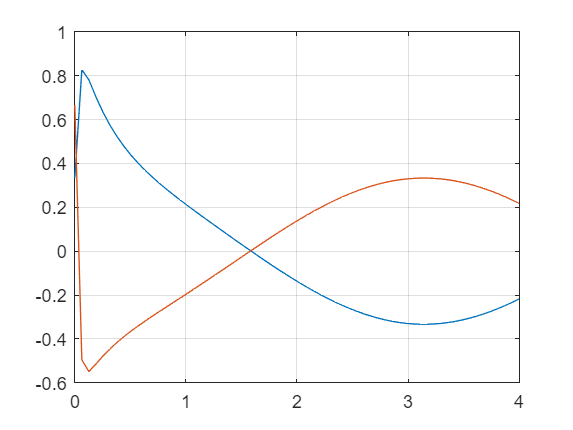

[t,y]=ode15s(f,rvt,ci);
figure, plot(t,y), grid

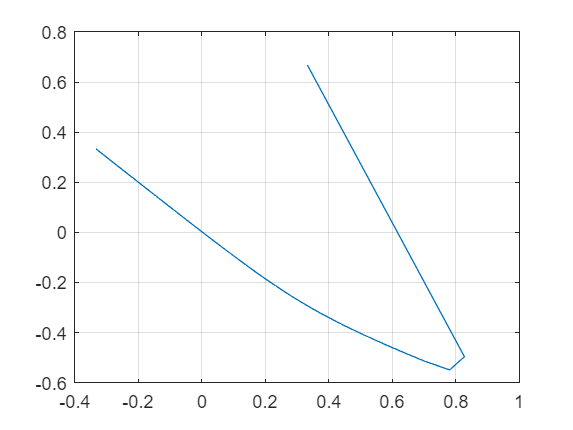

figure, plot(y(:,1),y(:,2)), grid

Lo volvemos a resolver pero ahora cambiando el error.

a=odeset('RelTol',1e-8);
rvt=linspace(0,4,2^6)

rvt =          0    0.0635    0.1270    0.1905    0.2540    0.3175    0.3810    0.4444    0.5079    0.5714    0.6349    0.6984    0.7619    0.8254    0.8889    0.9524    1.0159    1.0794    1.1429    1.2063    1.2698    1.3333    1.3968    1.4603    1.5238    1.5873    1.6508    1.7143    1.7778    1.8413    1.9048    1.9683    2.0317    2.0952    2.1587    2.2222    2.2857    2.3492    2.4127    2.4762    2.5397    2.6032    2.6667    2.7302    2.7937    2.8571    2.9206    2.9841    3.0476    3.1111


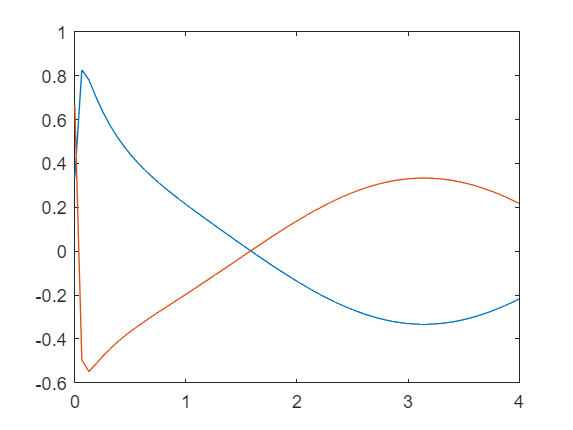

[t1,y1]=ode15s(f,rvt,ci);
plot(t1,y1)

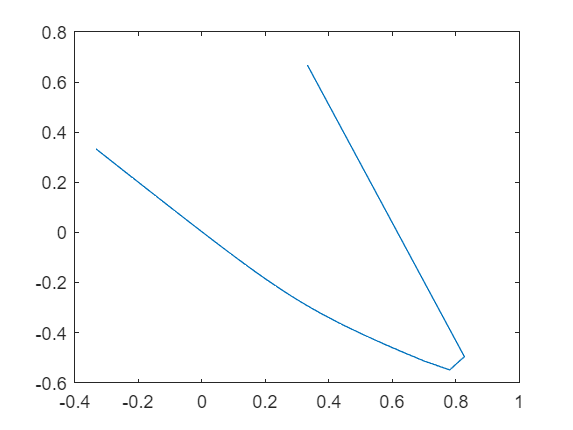

plot(y1(:,1),y1(:,2))

Lo vemos con ode

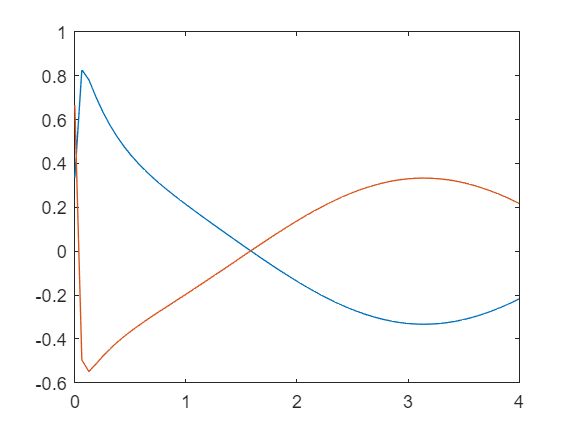

rvt=linspace(0,4,2^6);
[t2,y2]=ode45(f,rvt,ci);
plot(t2,y2)

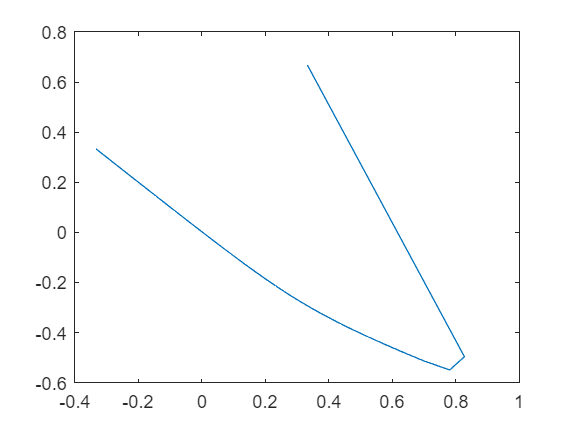

plot(y2(:,1),y2(:,2))

Ahora cambiamos el error relativo en la ode

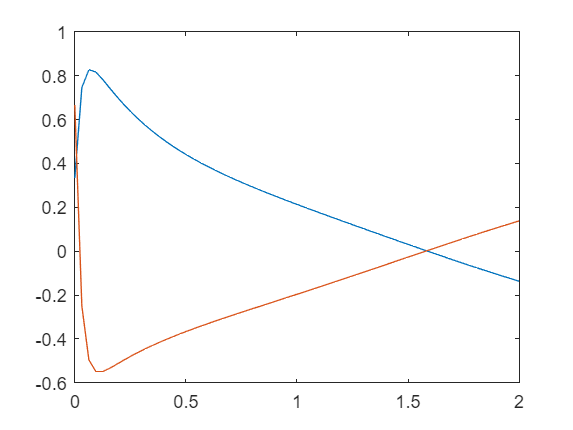

rvt=linspace(0,4,2^6);
a=odeset('RelTol',1e-10);
[t3,y3]=ode45(f,rvt,ci);
plot(t3,y3)

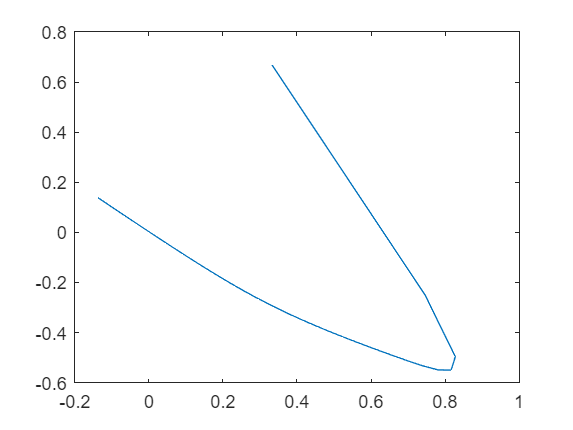

plot(y3(:,1),y3(:,2))

Segundo sistema de ecuaciones


$$y\prime_1(t) =-0.1y_1(t) - 49.9y_2(t), \;\;\; y_1(0)=1$$



$$y\prime_2(t) = -50y_2(t), \;\;\; y_2(0)=2$$



$$y\prime_3(t)=70y_2(t) - 120 y_3(t), \;\;\; y_3(0)=1$$


Definimos las varibles de estado como 


$$y_1(t)=y(1), \;\;\; y_2(t)=y(2), \;\;\; y_3(t)=y(3)$$


Se sigue que 

f1=@(t,y) [-0.1*y(1)-49.9*y(2);-50*y(2);70*y(2)-120*y(3)];

Escribimos las condiciones iniciales y el rango de valores de t

rvt=linspace(0,0.1,2^7);
a=odeset('RelTol',1e-8);
ci=[1;2;1];

Ahora resolvemos la ecuacion y graficamos

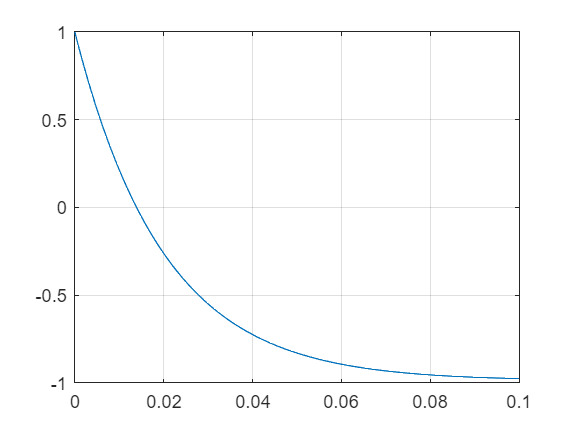

[t,y]=ode15s(f1,rvt,ci,a);
figure,plot(t,y(:,1)), grid

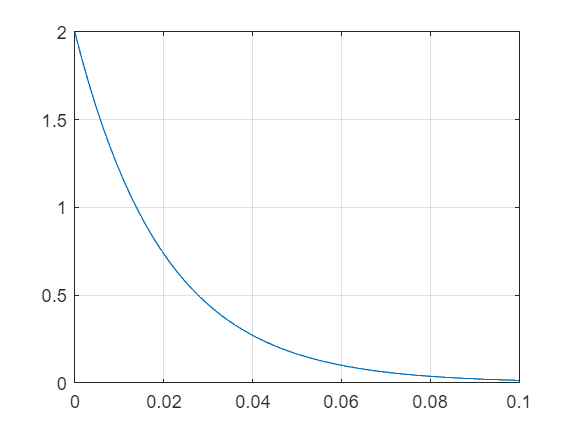

figure,plot(t,y(:,2)), grid,

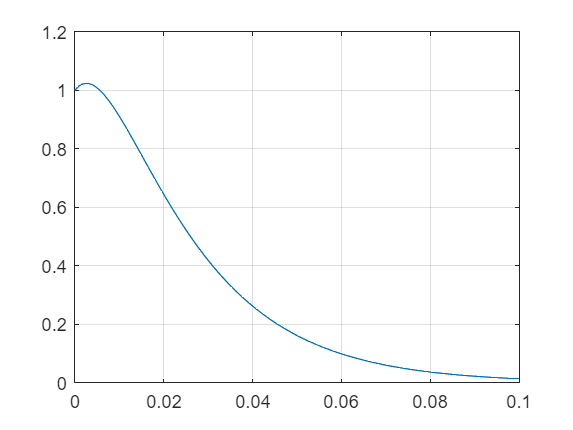

figure,plot(t,y(:,3)), grid,